# Asesoria Métodos Númericos

### Asesoria 19/04/2022

### Asesoria 19/04/2022

clear
syms F(x, y, z)

F(x, y, z) = [2*x^3; x - y^2; z^2];

jacobian(F, [x, y, z])

$$ans(x, y, z) = \left(\begin{array}{ccc} 6\,x^{2} & 0 & 0\\ 1 & -2\,y & 0\\ 0 & 0 & 2\,z \end{array}\right)$$

clear
syms x y

yVal = [9.8 9.5 9.8 9.9 10.1 10.4]

yVal =     9.8000    9.5000    9.8000    9.9000   10.1000   10.4000


xVal = 2000:2005

xVal =         2000        2001        2002        2003        2004        2005


help newpoly

  Entrada   - X es un vector que contiene la lista de abscisas
            - Y es un vector que contiene la lista de ordenadas
  Saldia    - C es un vector que contiene los coeficientes del
              polinomio interpolante de Newton
            - D es la tabla de diferencias divididas



help lagran

  Entrada  - X es un vector que contiene una lista de las abscisas
           - Y es un vector que contiene una lista de las ordenadas
  Salida   - C es una matriz que contiene los coeficientes del
             polinomio interpolante de Lagrange
           - L es una matriz que contiene los coeficientes de los
             polinomios de Lagrange



[c, d] = newpoly(xVal, yVal)

c = 	1.0e+14 *

   -0.0000    0.0000   -0.0000    0.0000   -0.0094    3.7594


d =     9.8000         0         0         0         0         0
    9.5000   -0.3000         0         0         0         0
    9.8000    0.3000    0.3000         0         0         0
    9.9000    0.1000   -0.1000   -0.1333         0         0
   10.1000    0.2000    0.0500    0.0500    0.0458         0
   10.4000    0.3000    0.0500    0.0000   -0.0125   -0.0117


F = @(x) polyval(c, x)

F = function_handle with value:
    @(x)polyval(c,x)


Pendientes = d(2:end, 2)

Pendientes =    -0.3000
    0.3000
    0.1000
    0.2000
    0.3000


%y=[9.8 9.5 9.8 9.9 10.1 10.4]
%x=[2000 2001 2002 2003 2004 2005]
Pendientes(1)

ans = -0.3000

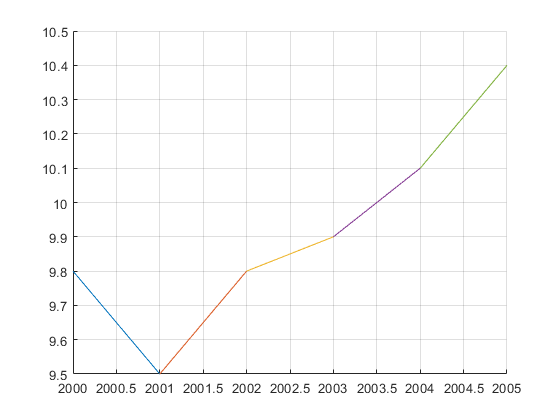

clf('reset')
hold on

for k = 1:5
    F = y - yVal(k) - Pendientes(k)*(x - xVal(k));
    fimplicit(F, [xVal(k) xVal(k +1) 9.5 10.4]);
end

grid on
hold off

Creemos de 2 maneras distintas el polinomio interpolante de una función $f\left(x\right)$ usando los polinomios de chebyshev, usaremos la combinación de coeficientes, y el uso de nodos.

clear
syms f(x) C(x)

f(x) = log(x + 2); % Defino una función

Primero hagamos uso de los nodos entre 0 y 1:

f = matlabFunction(f);

[~, X, Y] = cheby(f, 5, -1, 1) % Generamos los nodos

X =     0.9659    0.7071    0.2588   -0.2588   -0.7071   -0.9659


Y =     1.0872    0.9959    0.8148    0.5546    0.2569    0.0335


C = newpoly(X, Y); % Generamos el polinomio

N = @(x) polyval(C, x); % Función que evalue el polinomio

Gráfiquemos y veamos la aproximación

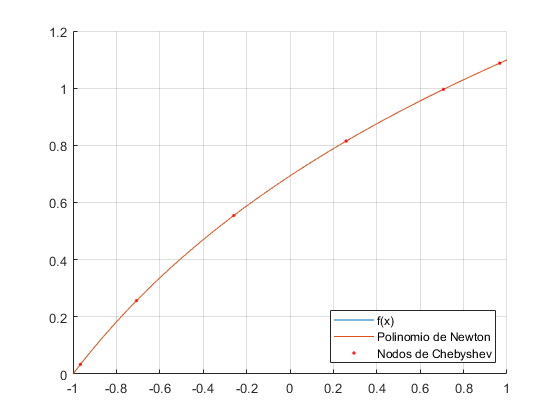

clf('reset')
hold on
fplot(f, [-1, 1])
fplot(N, [-1, 1])
plot(X, Y, '.r')
legend('f(x)', 'Polinomio de Newton', 'Nodos de Chebyshev', 'Location','southeast')
grid on
hold off

Ahora hagamos uso de la combinación de polinomio de Chebyshev, así:

[T] = cheby(f, 3, -1, 1) % Generamos los coeficientes para la combinación

T =     0.6238    0.5359   -0.0717    0.0123


Cheby(x) = dot(T, chebyshevT(0:3, x)); % Definimos la combinación
Cheby = matlabFunction(Cheby);

Gráfiquemos y veamos la aproximación

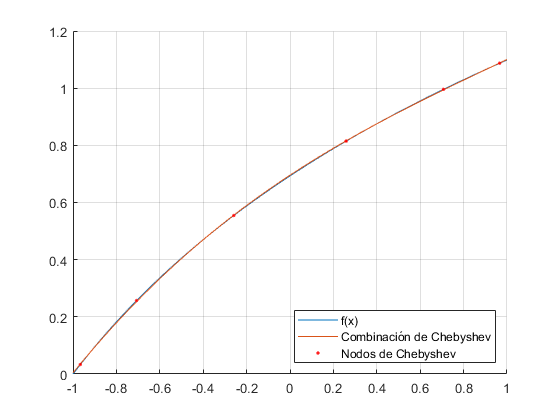

clf('reset')
hold on
fplot(f, [-1, 1])
fplot(Cheby, [-1, 1])
plot(X, Y, '.r')
legend('f(x)', 'Combinación de Chebyshev', 'Nodos de Chebyshev', 'Location','southeast')
grid on
hold off